close all
clear
clc

The objective of this demo is to show an example of **EMG processing** implementation in different scenarios involving EMG signal transmission for real-time applications. 

To provide a more practical example we use a signal contained in a .mat file that it has to be loaded. This file contains a raw EMG signal at sampling rate *fs=2000 Hz*. 

% Load the EMG signal
load raw_EMG.mat

% EMG features 
fs = 2000; % Sampling frequency [Hz]
N = length(raw_EMG); % Signal length
t = (0:N-1)/fs; % Time vector [s] [seconds: samples* s/samples]

For general knowledge we visualize the signal in time and its frequency spectrum. 

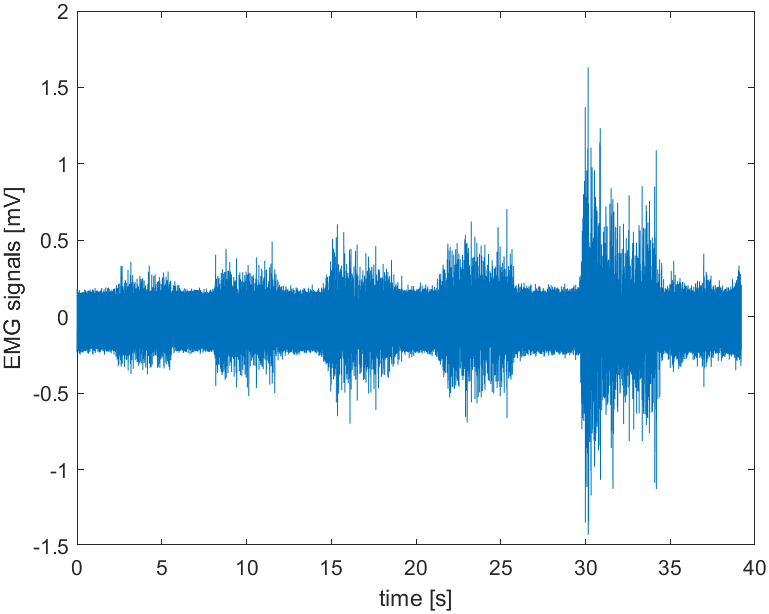

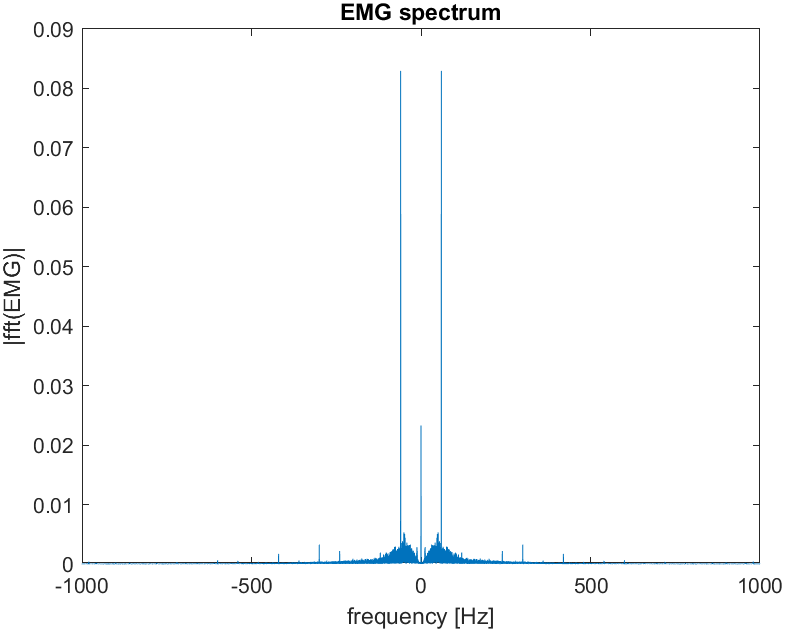

For surface EMG signals, the PSD presents the largest area between 30 and 150 Hz, but the overall range is 10-500 Hz. 

In this case, a noise component is noticeable on the signal. The main noise component is poweline interference (50 Hz EU and 60 Hz USA) and its harmonics (not always all present), other low-frequency noise components, and motion artifacts (between acquisition electrode and skin or of the subject itself). 

EMG processing involves various combinations of filters, such as: low pass, high-pass, band-pass, or notch filters [1].

The choice of combination depends on the use of the signal after processing (biofeedback/actuation or clinical assessment). The choice of filter type and specifications is crucial in achieving effective noise reduction while preserving the relevant muscle activity features. Of particular concern, especially if the EMG signal is to be leveraged as biofeedback, is the delay accumulated by the filters during processing. It is necessary in this case to find the right trade-off between noise reduction and filter delay to make the processing as fast as possible.

Two different types of digital filters are generally used, IIR (Infinite impulse response) filters and FIR (Finite impulse response) filters. 

Filter delay depends on its order. For an FIR filter, this is N-1, with N equal to the number of  taps (coefficients of its kernel).

While FIR filters can be designed to have linear phase response (by symmetry or antisimmetry in the impulse response), IIR filters  never exhibit linear phase. However, IIR filters are more efficient, as they allow obtaining shorter transition bands than FIR filters, for the same order, when linear phase characteristics are not strictly required. This aspect can be exploited when EMG must be used in real time applications. In fact, in this case by using filter orders such as those mentioned above, the filter delay applied to the signal can be neglected.

Common design methods include Butterworth or Chebyshev. The Butterworth filter is characterized by a relatively smooth frequency response in the passband. The Chebyshev filter offers sharper roll-off, and the Elliptic filter maintains the steeper cut-off slope for the lower filter order, compared to Butterworth, but both introduce ripples in the passband, which might be a concern [1,2,3]. 

All the filters in this demo were generated with the Matlab filterDesigner tool. In the case of IIR filters what the tool returns to us is a .mat file containing an object with a second-order section (SOS) filter inside it. Fixed-point representation can be also extracted, along with block diagrams of different implementations and even HDL code. The partners can ask what they do prefer in this sense. The decomposition in biquad cells (second-order sections) is motivated by the containment of the quantization error. In the case of FIR filters, the tool returns a .mat file with a vector containing the numerator coefficients of the filter's frequency response. In both cases the output of the tool is used as input to the "filter" function to apply the designed filter to the EMG signal. The "filter" functions implements the input-output filter equation in order to obtain the output; a pre-initialization with zeros to have the output of the same lenght of the input is implemented.

Generally one of the noise components that most influences the analysis part of the EMG signal is the powerline interference with its harmonics. To remove that, according to the computational resources and the desired latency, we can think at applying:

- an IIR notch to the powerline interference (50 Hz EU, 60 Hz USA), 

- an IIR notch to the powerline interference and its odd harmonics (more frequently involved), 

- an IIR notch to the powerline interference and its harmonics (both even and odd).

After notching and bandpass filtering the raw EMG, the typical processing involves extracting the signal envelope and downsampling it at more reasonable sampling rates compared to the raw signal. The fastest performance can be achieved by rectifying the signal (to make it all positive) by absolute value extraction, and applying a moving average with a sliding window without any overlap (which involves a downsampling of a factor equal to the window length). 

In a more complex case, to get a more accurate envelope of the signal, we can extract the RMS of the signal, without any rectification, and with a sliding window without any overlap (which involves a downsampling of a factor equal to the window length). 

Depending on the length of the window, the extracted envelope is more or less smooth. 

Generally a subject does not perceive a very detailed envelope. A healthy subject naturally performs an integration of the envelope to exploit its essential information. A subject with a brain injury may have difficulty with this. In order to include this scenario in the demo, we implemented a moving window of sufficient length to make the signal smooth enough and a consequent overlapping. The system in this case always respects the desired output envelope frequency but accumulates a longer delay due to the length of the chosen window. 

If the system's latency is to be reduced, it is possible to adopt a moving window of a smaller length without any overlap.

The demonstrative demo realized includes three frameworks with progressively increasing complexity.

The fastest version of the processing might be as follows:

1) high-pass Butterworth filter  

2) notch at the main powerline interference (50/60 Hz) 

3) rectification by absolute value

4) moving average with overlap

This best suits the case where the EMG signal wants to be used as biofeedback (low delay).

The result of filtering is shown in the figure below:

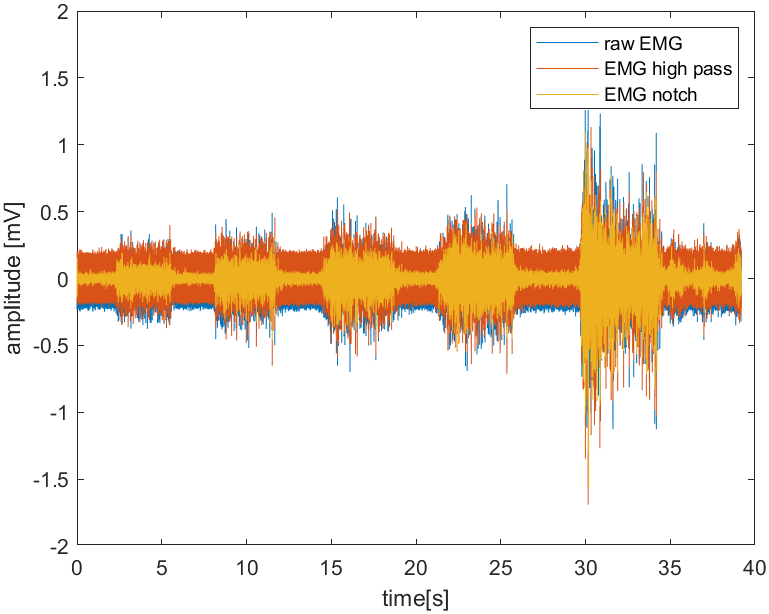

% High-pass Butterworth filter with lower order
load Hd_HP_BW.mat % Butterworth high-pass filter, order=4, fpass=20 Hz
EMG_high_pass_BW_only=filter(Hd_HP_BW, raw_EMG);


% Notch filter to remove only the 50 Hz powerline interference
load notch.mat % Notch filter, order=2; Fnotch=60 (for the signal of interest); Bandwidth=10
EMG_notch = filter(num_notch, den_notch, EMG_high_pass_BW_only);

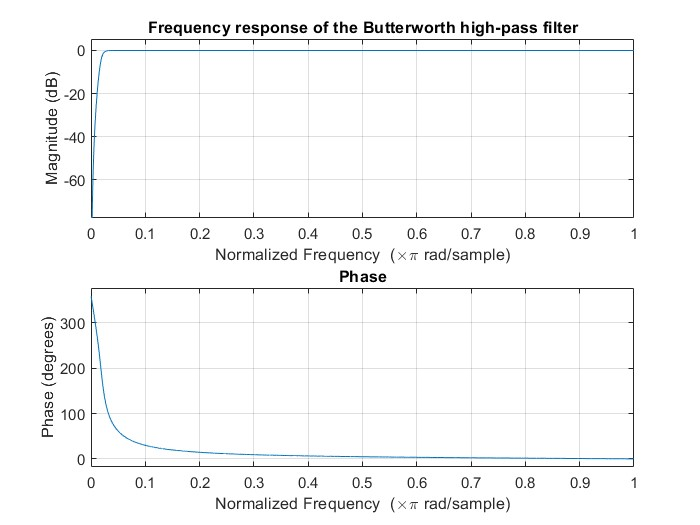

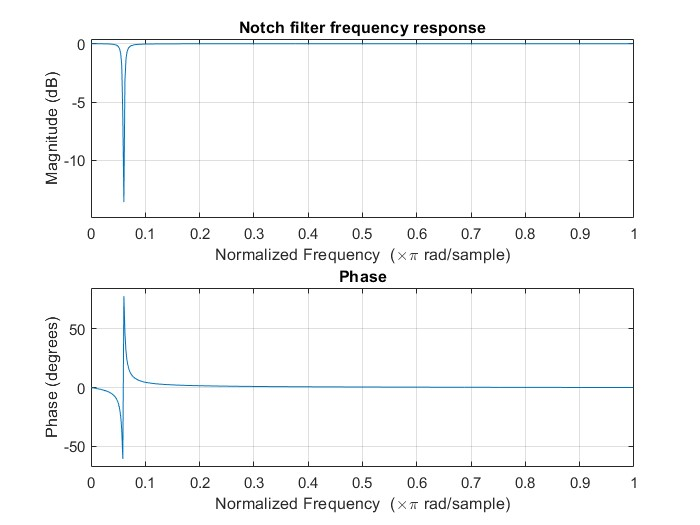

% Retification 
rectified_EMG= abs(EMG_notch);

If we consider that we need to transmit this envelope in order to use the  signal as biofeedback, we must make sure that the frequency is the right one for the application. In particular, the transmission frequency should not be too low as to impair motor performance.

Latency between a user's movement and visual feedback is an unavoidable component in any interactive system, due to the time required for signal transmission and processing. 

In addition, the sampling frequency transmitting_freq of the envelope output of the proposed system is 40 Hz, a design choice made considering the framerate of the Meta Quest 3 headset (36 Hz).

% Envelope estimation using window average and downsampling
transmitting_freq=40; % [Hz]
step = fs/transmitting_freq; % Window length for moving average (400 samples at fs=2000 Hz)
window_average_envelope=NaN(1,round(N/step));
count=0;
window_length=2*step;
for i = window_length:step:length(rectified_EMG)
    window = rectified_EMG(i-window_length+1:i);
    count=count+1;
    window_average_envelope(count)= mean(window);
end


The results of the just-proposed version are plotted on the right:

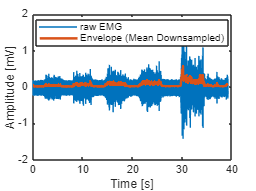

% Plot results of the firts version
figure
plot(t, raw_EMG);
hold on;
plot(t(1:step:end), window_average_envelope, 'LineWidth', 2);
hold off;
legend('raw EMG', 'Envelope (Mean Downsampled)','Location','best');
% title('Faster Version');
xlabel('Time [s]');
ylabel('Amplitude [mV]');

Another version combining the processing steps, with the different filters, might be as follows:

1) low-pass Butterworth filter 

2) high-pass Butterworth filter 

or 1-2) pass-band Chebichev or Elliptic filter

3) notch at the main powerline interference (50/60 Hz) and odd harmonics 

4) rectification 

5) moving average with overlap

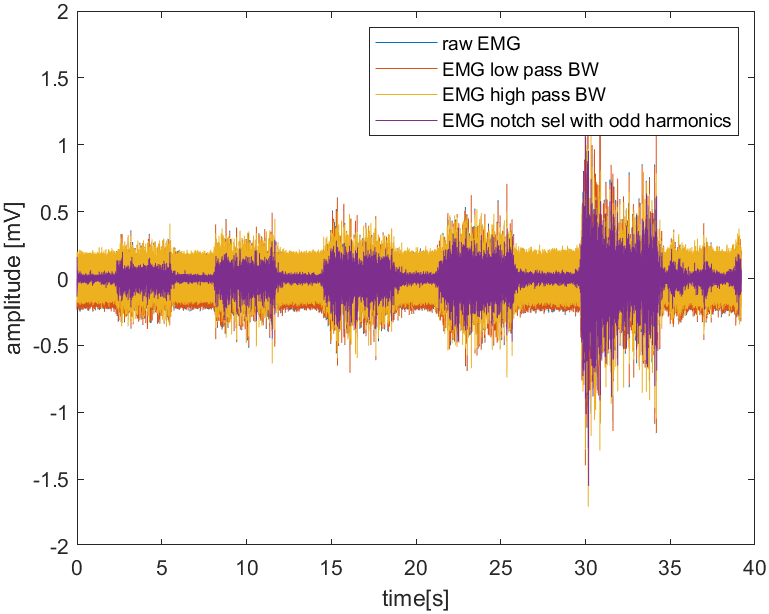

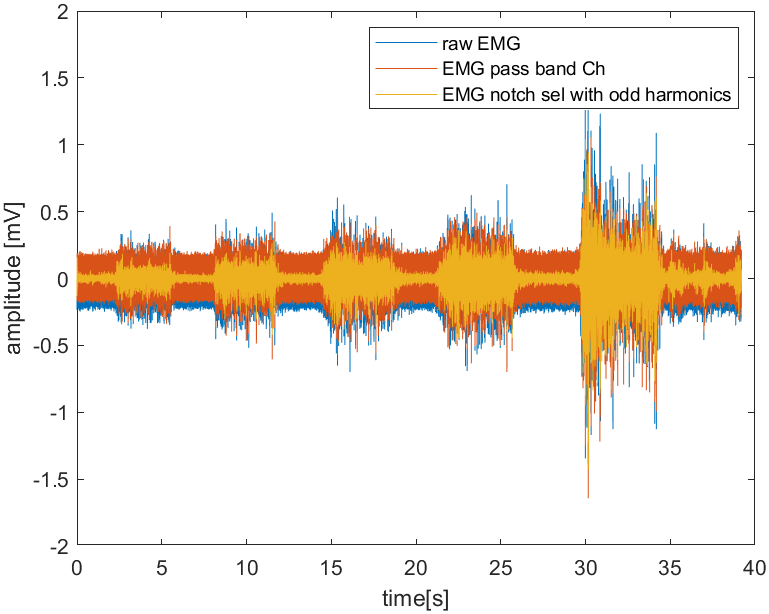

This best suits the case where the EMG signal wants to be used as biofeedback (low delay) but with a more precise noise removal.

% Low-pass Butterworth filter
load Hd_LP_BW.mat % Butterworth low-pass filter, order=4, fstop=450 Hz 
EMG_low_pass_BW = filter(Hd_LP_BW, raw_EMG);


% High-pass Butterworth filter with order=4, fpass=20 Hz
EMG_high_pass_BW = filter(Hd_HP_BW, EMG_low_pass_BW);


% Pass-Band Chebyshev II type (the stopband amplitude characteristics is
% equal ripple, but in the passband, it is monotonic)
load Hd_PB_Ch.mat % Pass-Band Chebyshev II type; order = 6, fpass1= 22 Hz fpass2= 425 Hz, Apass= 1
EMG_pass_band_Ch = filter(Hd_PB_Ch, raw_EMG);


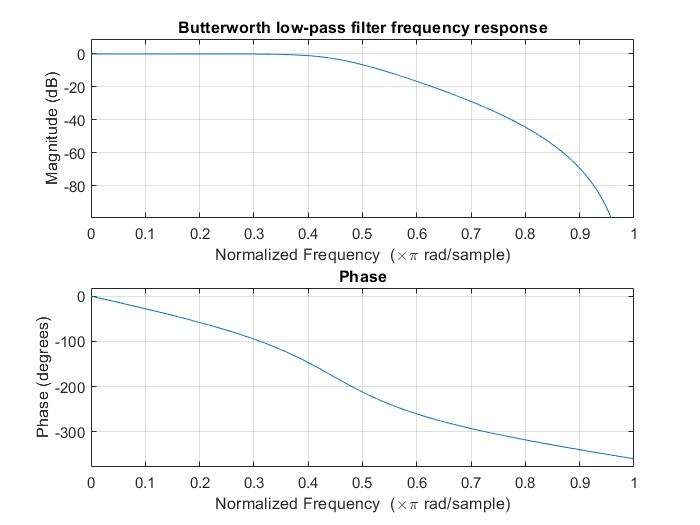

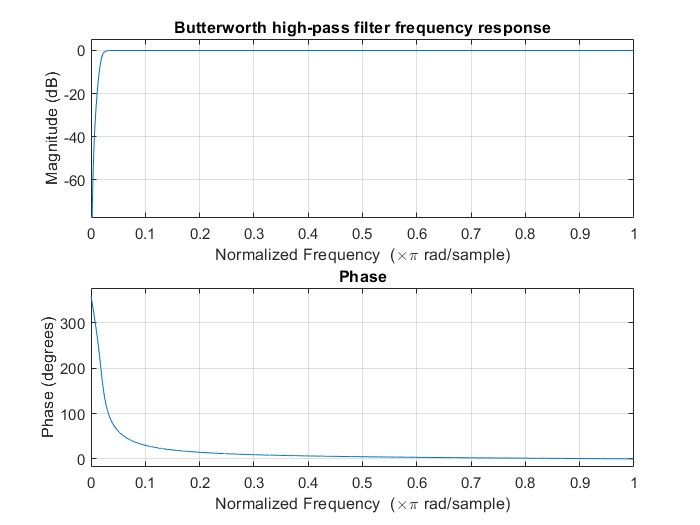

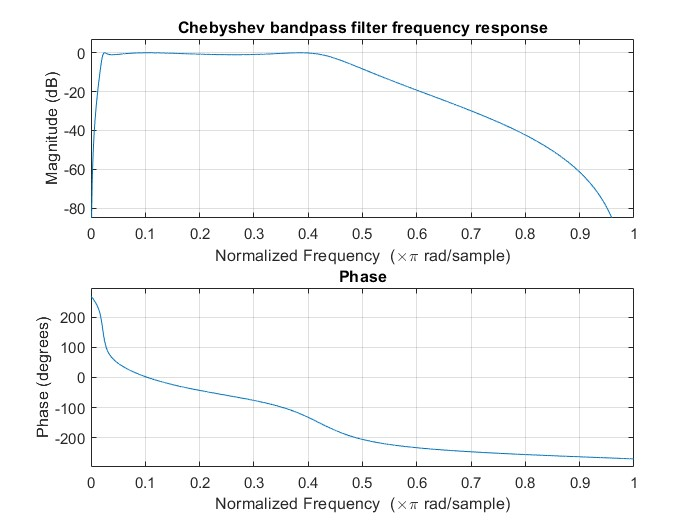

% notch filter: removes powerline interference and odd harmonics
f_notch=60; % [Hz]
bandwidth = 450; % Upper limit of the band [Hz]
odd_harmonics = f_notch:2*f_notch:bandwidth; 

EMG_notch_odd = EMG_high_pass_BW; % input signal for filter function
for harmonic = odd_harmonics
    EMG_notch_odd = filter(num_notch, den_notch, EMG_notch_odd);
end

% Retification 
rectified_EMG= abs(EMG_notch_odd);

% Envelope estimation using window average and downsampling
transmitting_freq=40; % [Hz]
step = fs/transmitting_freq; % Window length for moving average (400 samples at fs=2000 Hz)
window_average_envelope=NaN(1,round(N/step));
count=0;
window_length=2*step;
for i = window_length:step:length(rectified_EMG)
    window = rectified_EMG(i-window_length+1:i);
    count=count+1;
    window_average_envelope(count)= mean(window);
end

The results of the proposed version are plotted on the right:

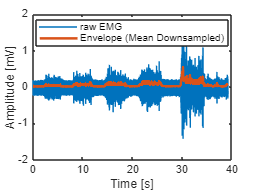

plot(t, raw_EMG);
hold on;
plot(t(1:step:end), window_average_envelope, 'LineWidth', 2);
hold off;
legend('raw EMG', 'Envelope (Mean Downsampled)','Location','best');
% title('Middle Version');
xlabel('Time [s]');
ylabel('Amplitude [mV]');

A version of the algorithm with linear phase filter might be as follows:

1) low pass filter equiripple FIR 

2) high pass filter equiripple FIR

3) notch at the main powerline interference (50/60 Hz) and all its harmonics 

4) RMS 

If we would like to have a filter with linear phase [6], we could use equiripple FIR filters. In this case the order of the filter grows. The option of a non-causal bidirection filter to have zero delay and constant zero phase does not apply to real-time scenarios. 

A good trade-off is not to accumulate too much delay especially if we want to use the signal in real-time applications. If the FIR filter is designed, the order is tens of hundreds of times higher than that of the IIR filter although it has a linear phase.

In this case the filter order is: 

1) low-pass= 127; N_coef=127; -->

delay_LP=(N_coef-1)/2=63 samples. @fs=2000 Hz this delay is equals to 0.0315 sec.

2) high-pass= 150; N_coef=150; -->

delay_HP=(N_coef)/2=75 samples. @fs=2000 Hz this delay is equals to 0.0375 sec.

% Equiripple FIR filters, which are more complex but provide a more precise frequency response.
% Low-pass Equiripple FIR filter with higher order
load Hd_LP_equiripple.mat % Equiripple FIR low-pass filter, order=127, fpass= 440 Hz, fstop=480; (-3db= 447 Hz) Apass=1; Astop=80
EMG_low_pass_eq = filter(Hd_LP_equiripple,1, raw_EMG);


% High-pass Equiripple FIR filter with higher order
load Hd_HP_equiripple.mat % Equiripple FIR high-pass filter, order=150, fstop= 5, fpass=25 (-3db = 20.75 Hz) Apass=1 Astop=40 
EMG_high_pass_eq = filter(Hd_HP_equiripple, EMG_low_pass_eq);


% notch filter: removes powerline interference and its harmonics
bandwidth = 450; % Upper limit of the band [Hz]
f_notch=60; % [Hz]
harmonics = f_notch:f_notch:bandwidth; 

EMG_notch_even_odd = EMG_high_pass_eq;
for harmonic = harmonics
    EMG_notch_even_odd = filter(num_notch, den_notch, EMG_notch_even_odd);
end


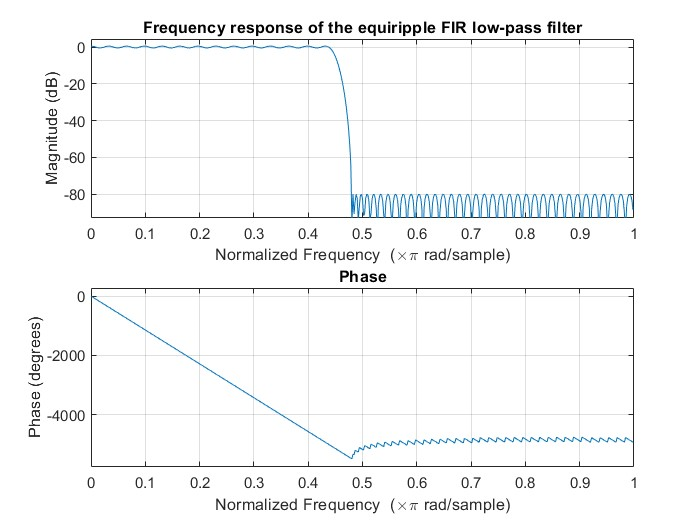

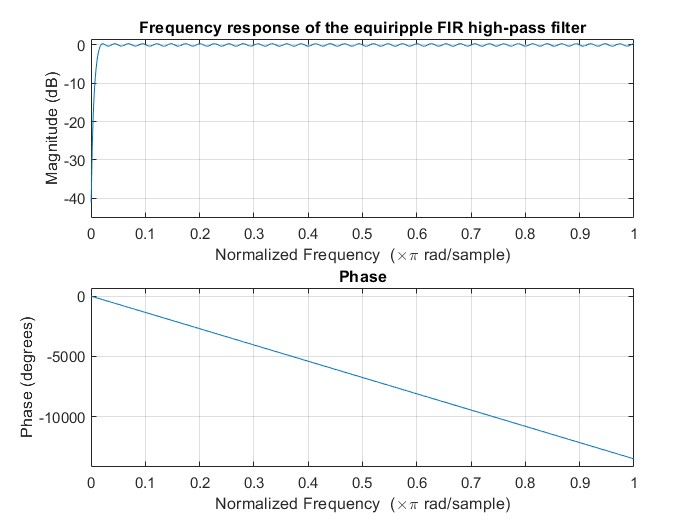

If we consider using the envelope for clinical purposes, we can also consider transmitting it with a samples per second higher than the previous scenarios (through upsampling).

% RMS calculation with a sliding window
transmitting_freq=40; % [Hz]
step = fs/transmitting_freq; % Window length for moving average (400 samples at fs=2000 Hz)
rms_envelope=NaN(1,round(N/step));
count=0;
window_length=2*step;


for i = window_length:step:length(EMG_notch_even_odd)
    count=count+1;
    rms_envelope(count) = sqrt(mean(EMG_notch_even_odd(i-window_length+1:i).^2));
end


This best suits the case where the EMG signal wants to be used as clinical purposes (more accurate filtering and enveloping).

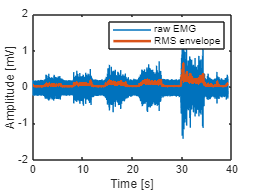

% Plot results of the complex version
figure;
plot(t, raw_EMG);
hold on;
plot(t(1:step:end), rms_envelope, 'LineWidth', 2);
hold off;
legend('raw EMG', 'RMS envelope');
% title('Complex Version');
xlabel('Time [s]');
ylabel('Amplitude [mV]');

The provided coefficients are for double-precision floating point representation (Matlab). A fixed-point implementation can be determined. However, in that case, the square root for the RMS computation could represent a problem. The partners should say if they have possibility of performing it or if another technique, such as ARV, which is common in EMG processing, should be better used. Moreover, pay attention to the internal resolution, in case of RMS, as you need to accumulate several squared values before taking the square root.

Despite this demo reports a batch sequential processing, because of the streaming nature of the application, sample by sample processing must be implemented in Myrtus. 

To extract parameters related to maximum muscle activation from the envelope, it would be necessary to have the user perform exploratory movements in an initial phase that we can define as ‘exploratory’. From this phase I calculate the MVC (Maximal voluntary contraction) and use these values to normalise the signals at runtime. In this way it is possible to derive percentage values to be transmitted to the viewer as feedback on the entity of the contraction or even to be used to discretize with a number of levels (e.g. 5) the entity of the muscle contraction.

 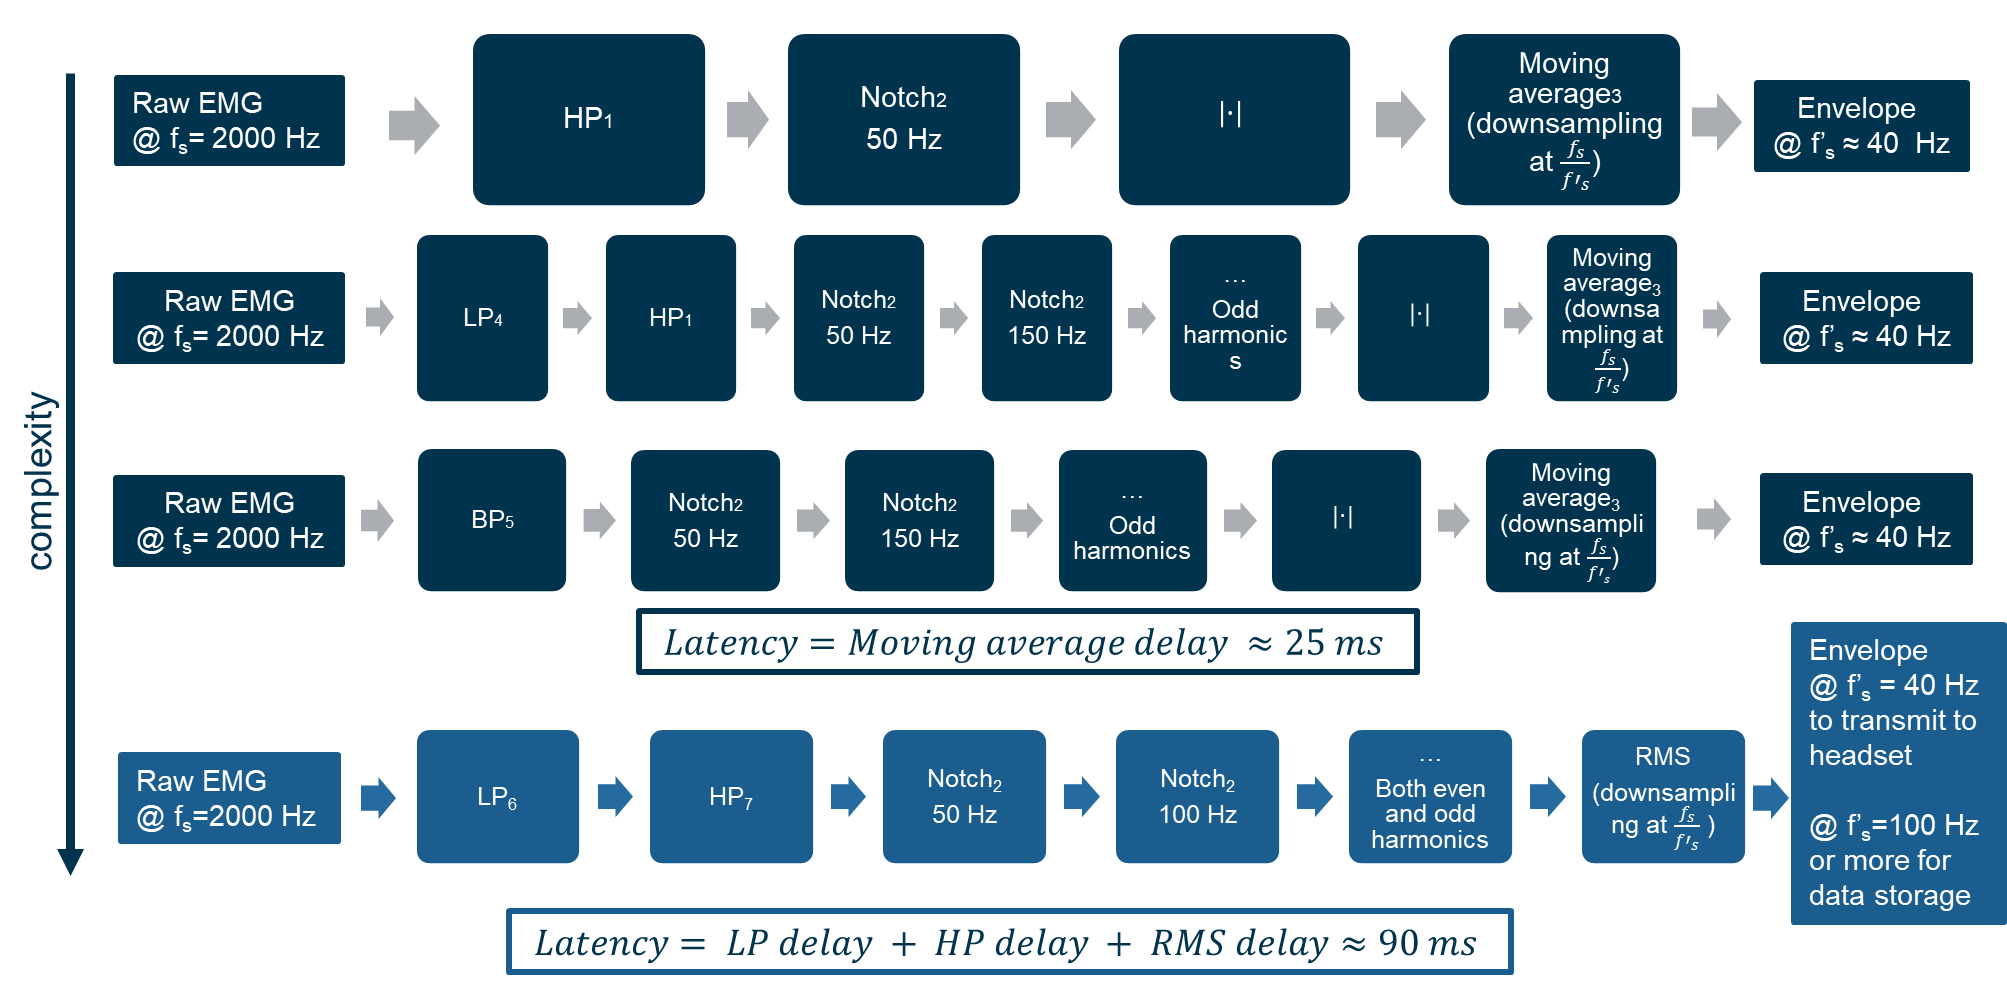

- *Butterworth high-pass filter*; **filter specifications**: order=4, fpass=20 Hz, **filter ****coeff**: Hd_HP_BW.matfile

- *Selective notch filter @50 Hz*; **filter specifications**: order=2; Fnotch=50; Bandwidth=10; filter coeff: notch.mat

- *Moving average (**downsampling**)*; **window length**= 100 samples

- *Butterworth low-pass filter*; **filter specifications**: order=4, fstop=450 Hz; **filter ****coeff****: **Hd_LP_BW.mat

- *Pass-Band Chebyshev II type*; **filter specifications**:order = 6, fpass1= 22 Hz fpass2= 425 Hz, Apass= 1; **filter ****coeff**: Hd_PB_Ch.mat

- *Equiripple** FIR low-pass filter*; **filter specifications****: **order=127, fpass= 440 Hz, fstop=480; (-3db= 447 Hz) Apass=1; Astop=80;** filter ****coeff**: Hd_LP_equiripple.mat

- *Equiripple** FIR high-pass filter*, **filter specifications:** order=150, fstop= 5, fpass=25 (-3db = 20.75 Hz) Apass=1 Astop=40; **filter ****coeff****: **Hd_HP_equiripple.mat

**REFERENCES**

- Aparna, K., Vasantharaj, A., Ghosh, S., & Choksi, B. DEVELOPMENT OF HIGH-PERFORMANCE ANALOG AND DIGITAL FILTER FOR BIOMEDICAL SIGNAL PROCESSING.

- Xiao, Z., Ye, J., Shen, H., Deng, S., Zhu, H., & Xiao, H. (2023, April).Analysis of Digital Filtering Design Based on Surface EMG Signals. In2023 IEEE 3rd International Conference on Electronic Communications,Internet of Things and Big Data (ICEIB) (pp. 542-546). IEEE.

- De Luca, G. (2003). Fundamental concepts in EMG signal acquisition.Copyright Delsys Inc.

- (1994-2024 The MathWorks, Inc., Introduced before R2006a- resample- Resample uniform or nonuniform data to new fixed rate) from: [https://it.mathworks.com/help/releases/R2024b/signal/ref/resample.html?overload=resample+false](https://it.mathworks.com/help/releases/R2024b/signal/ref/resample.html?overload=resample+false)

- Waltemate, T., Senna, I., Hülsmann, F., Rohde, M., Kopp, S., Ernst, M., & Botsch, M. (2016, November). The impact of latency on perceptual judgments and motor performance in closed-loop interaction in virtual reality. In Proceedings of the 22nd ACM conference on virtual reality software and technology (pp. 27-35).

- Merletti, R. Standards for reporting EMG data. International Society of Electrophysiology and Kinesiology, 1999.

- Taha, Z., Deboucha, A., Ahamed, N. U., Ahmed, N., Ariffin, R.Ghazilla, R., ... & Wong, Y. (2015). IIR filter order and cut-off frequency influences on EMG signal smoothing. Biomedical Research, 26(4), 616-620.

- Lu, C., Xu, X., Liu, Y., Li, D., Wang, Y., Xian, W., ... & Tian, J. (2024). An Embedded Electromyogram Signal Acquisition Device. Sensors, 24(13), 4106